# ViconExtract main

run to open gui with vesettings

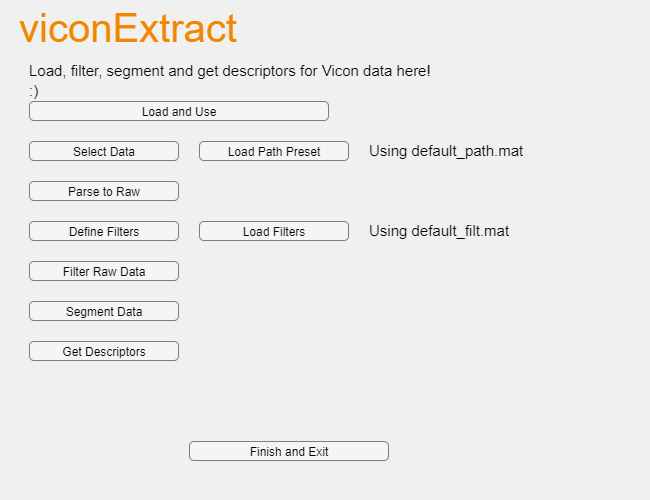

addpath(genpath(pwd));  % PWD maximum depth is ...\viconExtract to run
vesettings = importsettings();
ve_gui = ViconExtract_gui();

Runtime settings

function vesettings = importsettings()
    vesettings = struct('dontuse', 'dontuse');

    % Vicon frequency
    vesettings.vicon_freq = 100; % Hz

    % segment_strides Interpolation Number
    vesettings.n_interp = 100;

    % segmentation z-score threshold for stride outlier removal
    vesettings.zscoremax = 3;   % default is 3

    % OVERRIDES SECTION
    % import_overrideallows importing and using of unknown/invalid .mat files
    vesettings.import_override = false;     % default is false

    % forceplatez_override forces program to use existing forceplate_force_z for segmentation
    % override may cause unintended/faulty behavior from GRFSegment
    vesettings.forceplatez_override = true;    % default is true
    
    vesettings = rmfield(vesettings, 'dontuse');
end